# Proyecto Integrativo Procesamiento de Señales

## Procesamiento de Imágenes de Accidente Cerebrovascular Mediante MRI

### Equipo: Arellano, Bravo, González e Isoard

#### Desarrollo:

Descargar la carpeta 'Brain_Data_Organized' de la página [https://www.kaggle.com/afridirahman/brain-stroke-ct-image-dataset](https://www.kaggle.com/afridirahman/brain-stroke-ct-image-dataset) la cual contiene dos subcarpetas 'Normal' y 'Stroke', que a su vez contienen una serie de imágenes en el plano axial. 

MainDirH='C:\Users\fabio\Dropbox\PC\Desktop\Proyecto Final Señales\Brain_Data_Organised\1\Healthy';
MainDirS='C:\Users\fabio\Dropbox\PC\Desktop\Proyecto Final Señales\Brain_Data_Organised\1\Stroke';

imdsH = imageDatastore(MainDirH, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

imdsS = imageDatastore(MainDirS, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');


numHImages = numel(imdsH.Files);
numSImages = numel(imdsS.Files);

Una ves obtenida el total de imágenes contenidas de ambas carpetas procederemos a modificar el tamaño de nuestras imágenes originales, para así, poder agilizar la simulación.

for k=1:numHImages
    I = readimage(imdsH,k);
    I2=imresize(I,0.5);
    %Dentro de nuestra carpeta original se deberán crear otras dos
    %subcarpetas donde se guardarán las imágenes modificadas
    nom2='C:\Users\fabio\Dropbox\PC\Desktop\Proyecto Final Señales\Brain_Data_Organised\2\Healthy M\';
    n=num2str(k);
    nom3= strcat(nom2,n);
    nombreout=strcat(nom3,'.jpg');
    imwrite(I2,nombreout);      
end

for k=1:numSImages
    I = readimage(imdsS,k);
    I2=imresize(I,0.5);
    nom2='C:\Users\fabio\Dropbox\PC\Desktop\Proyecto Final Señales\Brain_Data_Organised\2\Stoke M\';
    n=num2str(k);
    nom3= strcat(nom2,n);
    nombreout=strcat(nom3,'.jpg');
    imwrite(I2,nombreout);
end

MainDirF='C:\Users\fabio\Dropbox\PC\Desktop\Proyecto Final Señales\Brain_Data_Organised\2\';

imdsF = imageDatastore(MainDirF, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

perm = randperm(1000,25);
numTrainingImages = numel(imdsF.Files);
%La secuencia obtendra sus muestras del total para arrojar una matrix de (2501x25)
for i = 1:25
    subplot(5,5,i);
    imshow(imdsF.Files{perm(i)});
end
labelCount = countEachLabel(imdsF)

labelCount = 2×2 table
      Label      Count
    _________    _____

    Healthy M    1551 
    Stoke M       950 


A continucación se deberá definir el numero de imagenes que conteneran nuestras dos categorías; 'Normal' y 'Stroke'.

numTrainFiles=500;
numValidFiles = 250;
numTestFiles = 150;
[imdsTrain,imdsValidation, imdsTest] = splitEachLabel(imdsF,numTrainFiles,numValidFiles,numTestFiles,'randomize');

layers = [
    imageInputLayer([325 325 1])
    
    convolution2dLayer(6,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(4,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(4,'Stride',2)
    
    convolution2dLayer(6,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',8, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

Para este proyecto se decidió crear una trainNetwork para obtener una mejor visualización e interpretación de los resultados.

La primera ejecución consiste en la red1 basada en propiedades previamente establecidas: 

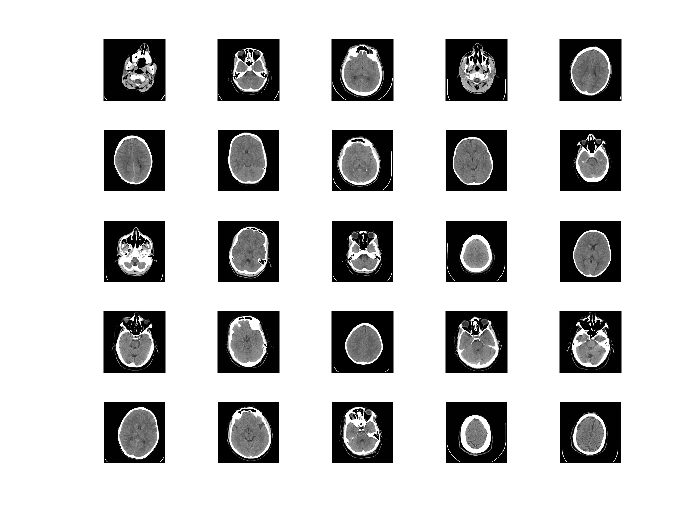

net1 = trainNetwork(imdsTrain,layers,options);


YPred = classify(net1,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = mean(YPred == YValidation)

accuracy = 0.8760


save net1;

La segunda ejecución consite en la red2 donde las propiedades han sido modificadas a valores previos a los de la red1:

numTrainFiles=400;
numValidFiles = 125;
numTestFiles = 375;
[imdsTrain,imdsValidation, imdsTest] = splitEachLabel(imdsF,numTrainFiles,numValidFiles,numTestFiles,'randomize');

layers = [
    imageInputLayer([325 325 1])
    
    convolution2dLayer(6,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(4,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(4,'Stride',2)
    
    convolution2dLayer(6,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',8, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress');

net2 = trainNetwork(imdsTrain,layers,options);

YPred = classify(net2,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = mean(YPred == YValidation)

accuracy = 0.8160


save net2;

La tercera ejecución consite en la red3 donde las propiedades han sido modificadas a valores posteriores a los de la red1:

numTrainFiles=600;
numValidFiles = 95;
numTestFiles = 205;
[imdsTrain,imdsValidation, imdsTest] = splitEachLabel(imdsF,numTrainFiles,numValidFiles,numTestFiles,'randomize');

layers = [
    imageInputLayer([325 325 1])
    
    convolution2dLayer(6,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(4,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(4,'Stride',2)
    
    convolution2dLayer(6,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer];

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',8, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',50, ...
    'Verbose',false, ...
    'Plots','training-progress');

net3 = trainNetwork(imdsTrain,layers,options);

YPred = classify(net3,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = mean(YPred == YValidation)

accuracy = 0.8526


save net3;

accuracy = 0.8000